addpath C:\Users\nlab\Desktop\GitHub\ratrix\analysis\KC\group_analyses_code

% load individual vars into group cell arrays
[nGroup, nthVarsFilePaths, groupStimDetails, groupSubjData, groupSubjName, groupDate, groupTrialCond, groupNumPreStimFrames, groupNumPostStimFrames, groupIdxOnsetsMeetsCriteria, groupOnsetDf, groupPeakFrameIdx, groupStimOnsetFrame, groupBaselineIdx, groupBaselinedActIm, groupRoundXpts, groupRoundYpts, groupPTSdfof, groupMeanSpeedAllTrials, groupIdxRunTrials, groupIdxStatTrials, groupIdxSmallPupilTrials, groupIdxLargePupilTrials, groupLongAxis, groupMeanPupilDiameterAllTrials, groupRunThresh, groupPupThresh, groupEarliestTrial, groupNumLateTrialsSubtract] = makeGroupStruct();

nGroup =      1


% of no pup data:
%[nGroup, nthVarsFilePaths, groupStimDetails, groupSubjData, groupSubjName, groupDate, groupTrialCond, groupNumPreStimFrames, groupNumPostStimFrames, groupIdxOnsetsMeetsCriteria, groupOnsetDf, groupPeakFrameIdx, groupStimOnsetFrame, groupBaselineIdx, groupBaselinedActIm, groupRoundXpts, groupRoundYpts, groupPTSdfof, groupMeanSpeedAllTrials, groupIdxRunTrials, groupIdxStatTrials, groupRunThresh] = makeGroupStruct_noPup();

% get stim conditions in order of trial & list of stim params to loop thru
% (This needs to be done new w/in the loop too each sess since the order of trialCond matters.. right now it's jsut to define cont & durat etc)
n = 1;
[durOrderedByTrialMeetCriteria,uniqueDurations,conOrderedByTrialMeetCriteria,uniqueContrasts,conAndDurOrderedByTrialMeetCriteria] = getStimParams4loops(n,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria);

% in preparation for making pixel wise figures of fluorescene at different stim conditions,
% make figure legends
[reigons,cons4Legend,cons4axes,durs4Legend,durs4Axes] = getSubtitleLegendNaxesInfo(uniqueContrasts,uniqueDurations);
reigons

reigons =     'V1'    'LP-HVA'    'LA-HVA'    'MA-HVA'    'control'


cons4Legend

cons4Legend =     '0'    '0.03'    '0.0625'    '0.125'    '0.25'    '0.5'    '1'


durs4Legend 

durs4Legend =     '6'


% group run & pupil distributions
meanSpeedAllTrials_eachSess = [];

clear n
for n = 1:nGroup
    
    % EXTRACT PEAK FRAMES BASELINE,and PTSDFOF
    nthMeanSpeedAllTrials = groupMeanSpeedAllTrials{1,n};
    meanSpeedAllTrials_eachSess = [meanSpeedAllTrials_eachSess,nthMeanSpeedAllTrials];
    
end 

% MAKE SURE ALL SESSIONS HAD SAME EARLIEST AND LATEST TRIAL (input to this function)
% FILTER first and last few trials... can change num trials in code
[runIdxOnsetsMeetsCriteria,meanSpeedAllTrials_eachSess] = filterOnsets_removeEarlyAndLateTrials(meanSpeedAllTrials_eachSess,groupEarliestTrial{1,n},groupNumLateTrialsSubtract{1,n});

sizeOnsetsMeetCriteria =            1        1662


sizeMeanSpeedAllTrials = size(meanSpeedAllTrials_eachSess)

sizeMeanSpeedAllTrials =            1        1662


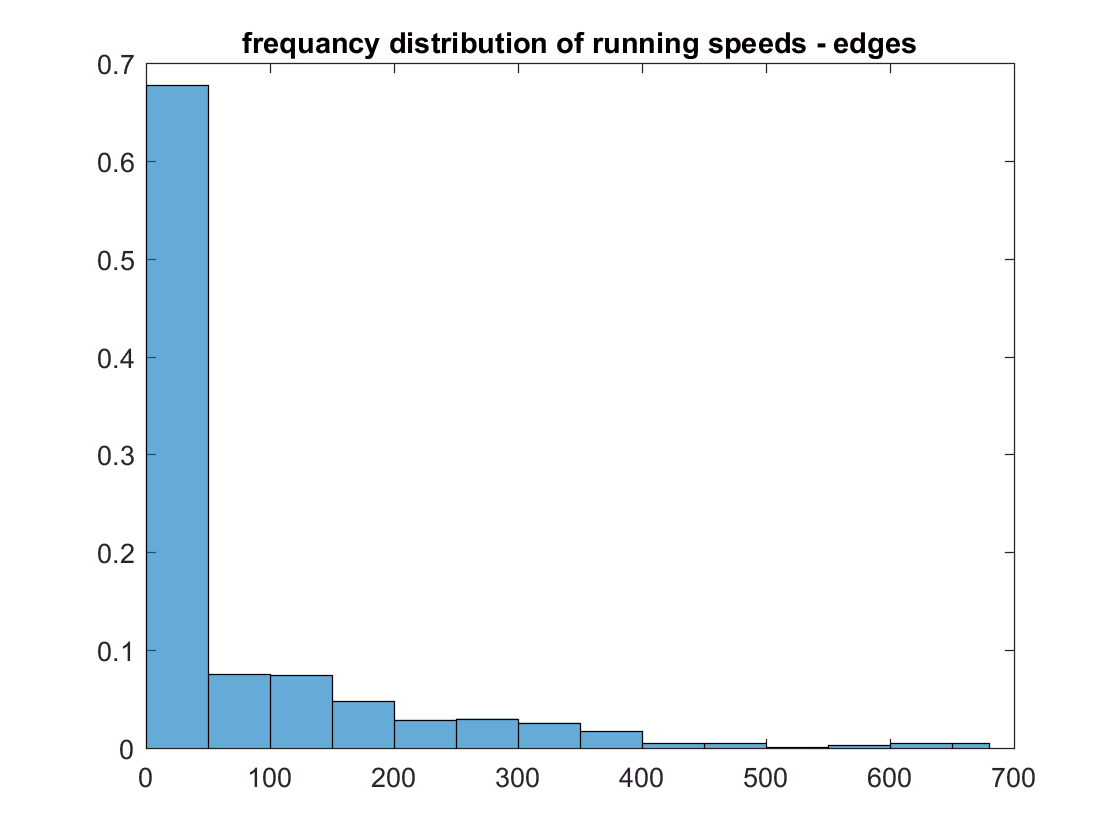


% HISTOs

%Bin edges, specified as a vector. edges(1) is the left edge of the first bin, 
%and edges(end) is the right edge of the last bin.
edges = [0 0:50:max(meanSpeedAllTrials_eachSess) max(meanSpeedAllTrials_eachSess)];
histogram(meanSpeedAllTrials_eachSess,edges,'normalization','probability')
%xlim([0 max(meanSpeedAllTrials_eachSess)])
%ylabel('percent of trials')
%xlabel('mean running speed')
title('frequancy distribution of running speeds - edges')


% alternately, use bins
%numTrials = length(meanSpeedAllTrials)
numBins = 10

numBins =     10


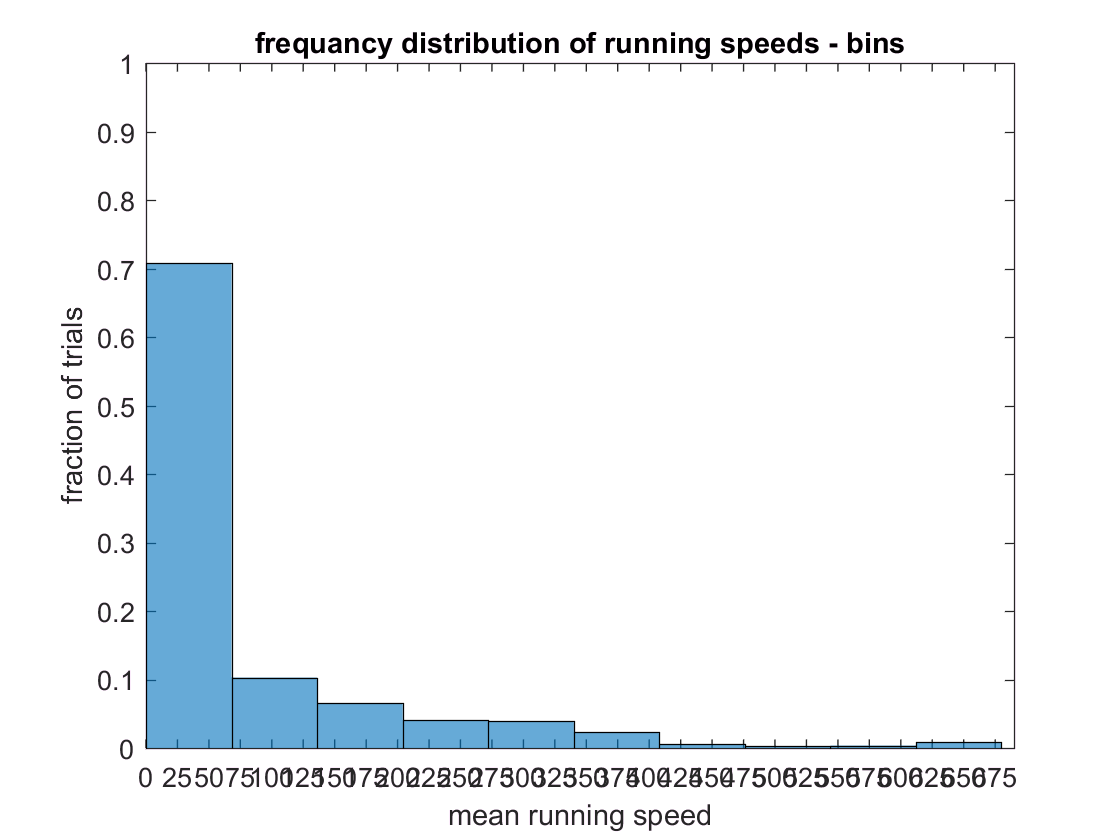

histogram(meanSpeedAllTrials_eachSess,numBins,'normalization','probability')
ylabel('fraction of trials')
xlabel('mean running speed')
title('frequancy distribution of running speeds - bins')
xlim([0 round(max(meanSpeedAllTrials_eachSess)+10)])
set(gca,'xtick',0:25:round(max(meanSpeedAllTrials_eachSess)+10));
ylim([0 1])


% PUPIL

meanPupDiameterAllTrials_eachSesss = [];

clear n
for n = 1:nGroup
    
    % EXTRACT PEAK FRAMES BASELINE,and PTSDFOF
    nthMeanPupDiameterAllTrials = groupMeanPupilDiameterAllTrials{1,n};
    meanPupDiameterAllTrials_eachSesss = [meanPupDiameterAllTrials_eachSesss,nthMeanPupDiameterAllTrials];
    
end 

% FILTER first and last few trials... can change num trials in code
[pupIdxOnsetsMeetsCriteria,meanPupDiameterAllTrials_eachSesss] = filterOnsets_removeEarlyAndLateTrials(meanPupDiameterAllTrials_eachSesss,groupEarliestTrial{1,n},groupNumLateTrialsSubtract{1,n});

sizeOnsetsMeetCriteria =            1        1662


sizemeanPupDiameterAllTrials = size(meanPupDiameterAllTrials_eachSesss)

sizemeanPupDiameterAllTrials =            1        1662


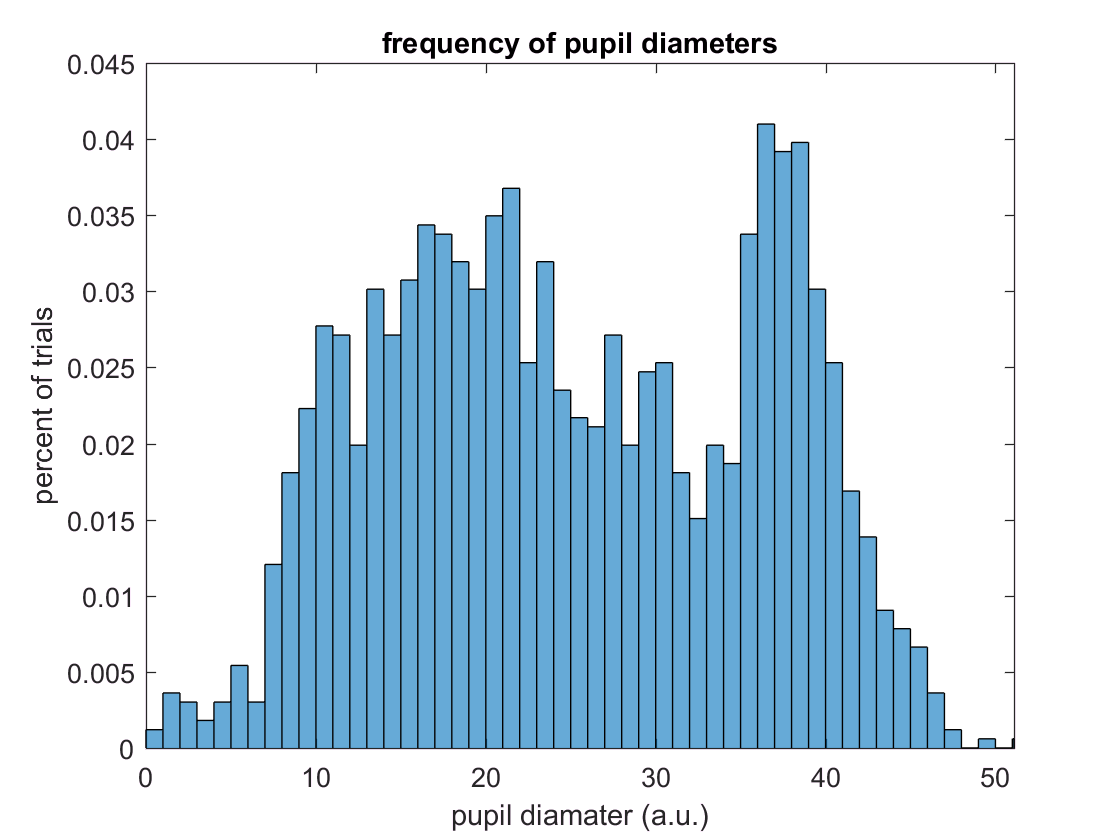


% HISTO
edges = [0 0:1:max(meanPupDiameterAllTrials_eachSesss) max(meanPupDiameterAllTrials_eachSesss)];
histogram(meanPupDiameterAllTrials_eachSesss,edges,'Normalization','probability')
xlim([0 max(meanPupDiameterAllTrials_eachSesss)])
title('frequency of pupil diameters')
xlabel('pupil diamater (a.u.)')
ylabel('percent of trials')

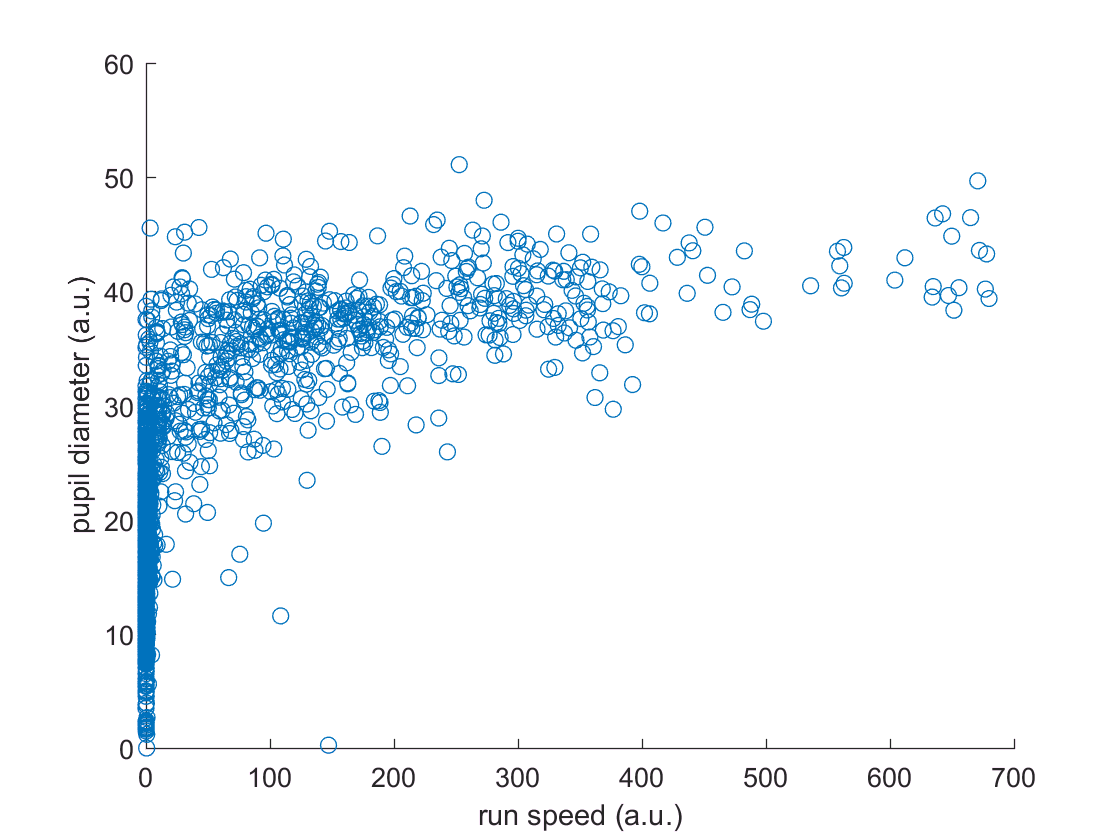


figure
scatter(meanSpeedAllTrials_eachSess,meanPupDiameterAllTrials_eachSesss)
xlabel('run speed (a.u.)')
ylabel('pupil diameter (a.u.)')

% HISTOs (need for stats stuff too) - # trials also in this code...

% LOCO

% getting distribtiion of trials via groupHisto() function
% plotting histos **AND** getting number of trials across all points, conditions etc

%durat = 1:length(uniqueDurations);
durat = 1

durat =      1


cont = 1:length(uniqueContrasts)

cont =      1     2     3     4     5     6     7


%cont = 7
visArea = 1:length(groupRoundYpts{1})

visArea =      1     2     3     4     5


%visArea = 1 % V1
%visArea = 2; % RL
%visArea = 3; % AL
%visArea = 4; % AM 
%visArea = 5; % control

sess = 1:nGroup

sess =      1



state = 'loRun'

state = loRun

[loRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial] = Histo_byBehState(nGroup,state,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria,groupPTSdfof,groupPeakFrameIdx,groupBaselineIdx,groupIdxStatTrials,groupIdxRunTrials,groupIdxLargePupilTrials,groupIdxSmallPupilTrials,visArea,durat,cont,conAndDurOrderedByTrialMeetCriteria,uniqueContrasts,uniqueDurations);
sizeLoRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial = size(loRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial)

sizeLoRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial =      1     1


% tip - index like this -
% allSess_allConsAllPtsAllDurs_pkDfEachTrial{1,n}{1,d}{1,i}{1,c}
state = 'hiRun'

state = hiRun

[hiRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial] = Histo_byBehState(nGroup,state,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria,groupPTSdfof,groupPeakFrameIdx,groupBaselineIdx,groupIdxStatTrials,groupIdxRunTrials,groupIdxLargePupilTrials,groupIdxSmallPupilTrials,visArea,durat,cont,conAndDurOrderedByTrialMeetCriteria,uniqueContrasts,uniqueDurations);
sizeHiRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial = size(hiRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial)

sizeHiRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial =      1     1


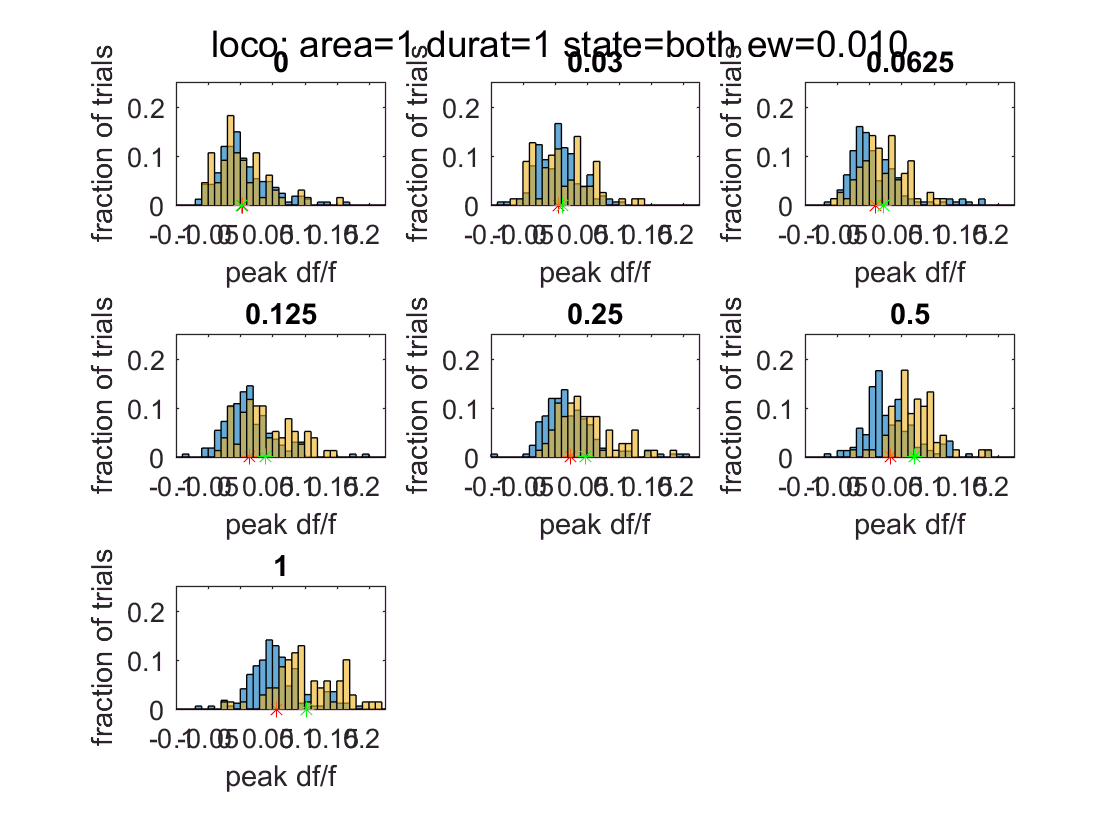

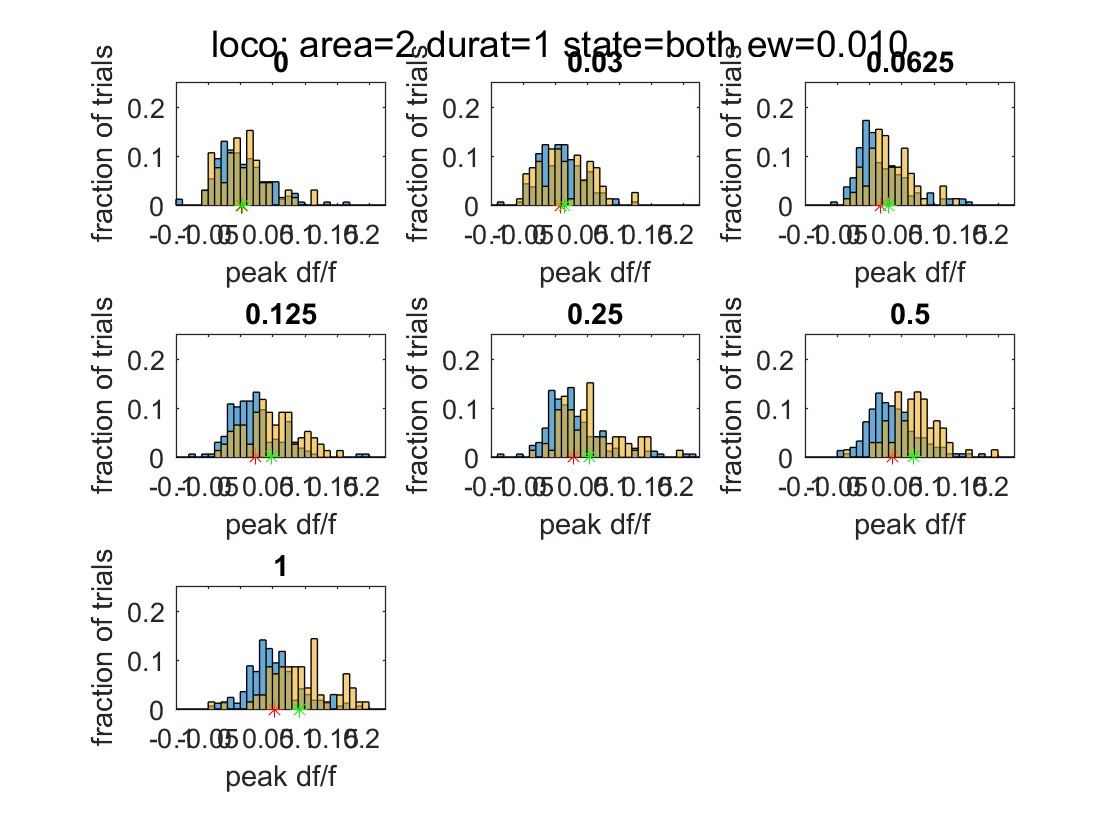

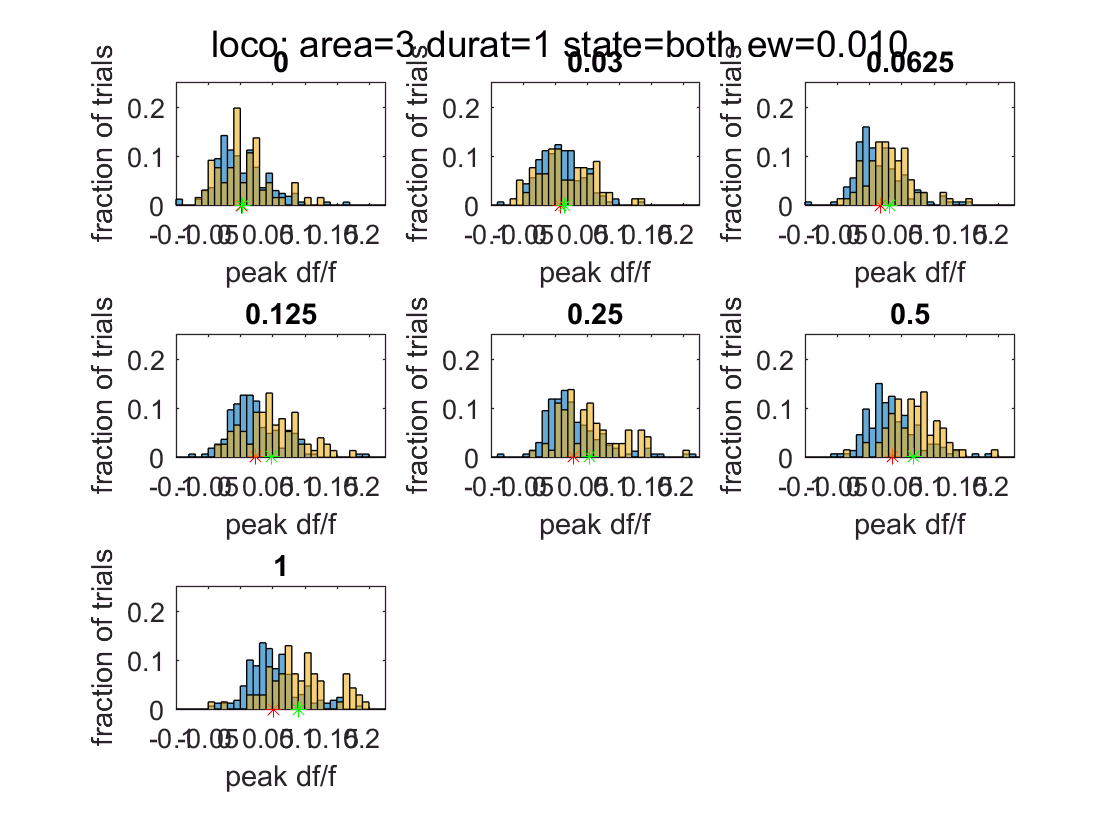

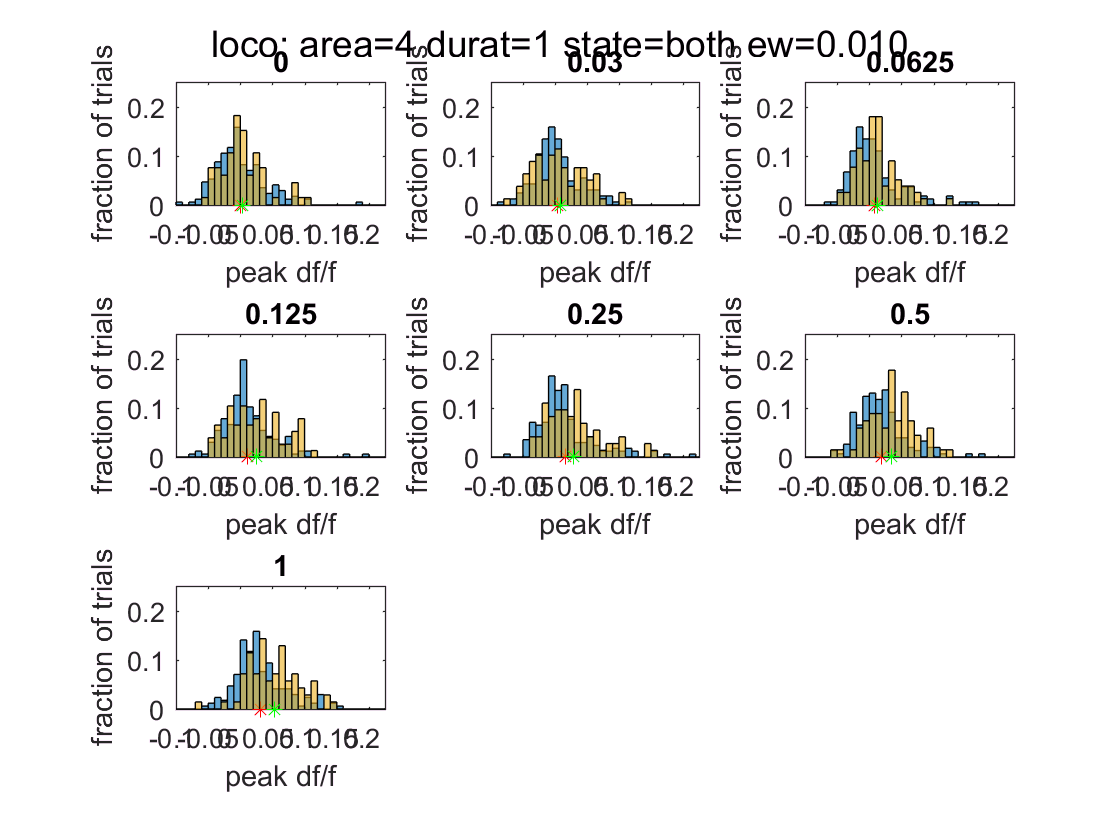

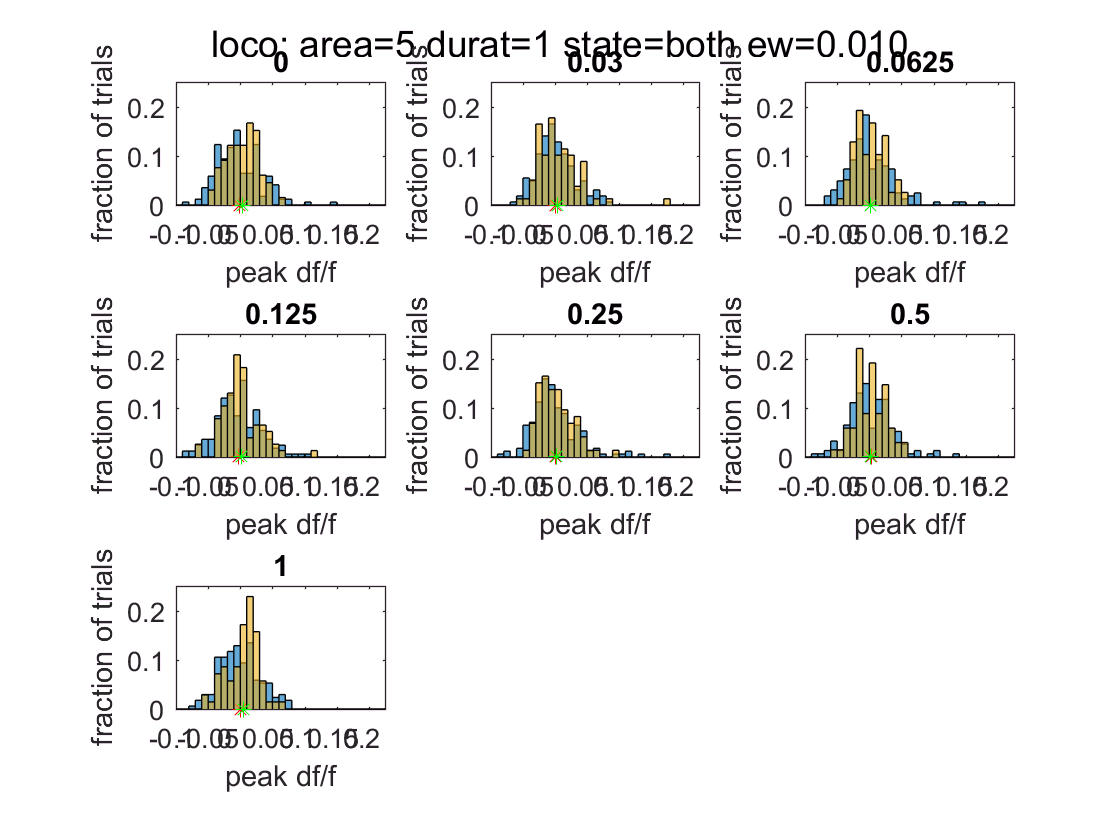

% tip - index like this -
% allSess_allConsAllPtsAllDurs_pkDfEachTrial{1,n}{1,d}{1,i}{1,c}

% both PLOT

yMax = 0.25;
yLimit = [0 yMax];

xMax = 0.225;
xMin = -0.1;
xLimit = [xMin xMax];

xTickRange = [xMin:0.05:xMax];
xTickLabelRange = [xMin:0.05:xMax];

edgeWidth = 0.01;
edges = [xMin xMin:edgeWidth:xMax xMax];
%numBins = 25;

% HISTO FIGS & num TRIAL matricies

clear loco_lo_numTrialsAllSess_AllConsAllPt
clear loco_lo_sumTrialsAcrossSess_AllConsAllPts
clear loco_lo_mnDf_allConsAllPt
clear loco_lo_stderr_allConsAllPt

clear loco_hi_numTrialsAllSess_AllConsAllPt
clear loco_hi_sumTrialsAcrossSess_AllConsAllPts
clear loco_hi_mnDf_allConsAllPt
clear loco_hi_stderr_allConsAllPt

clear d
for d = durat
   
    clear i
    %visArea = 5;
    for i = visArea 
        
        fig2 = figure;
        
        state = 'both';
        %formatSpec = 'c=%s, mn=%0.3f, st=%0.3f, n=%1.0f';
        formatSpec = 'loco: area=%1.0f durat=%1.0f state=%s ew=%0.3f'; % \n
        titleText = sprintf(formatSpec,i,d,state,edgeWidth);
        suptitle(titleText)
      
        clear lo_numTrialsAllSess_AllConsOnePt
        clear hi_numTrialsAllSess_AllConsOnePt
        
        clear lo_sumTrialsAcrossSess_AllConsOnePt 
        clear hi_sumTrialsAcrossSess_AllConsOnePt 
        
        clear lo_mnDf_allConsOnePt
        clear hi_mnDf_allConsOnePt
        
        clear lo_stderr_allConsOnePt
        clear hi_stderr_allConsOnePt
                 
        clear c
        for c = cont
            
            % emty matricies to add different number of trials to each time thru sessions loop (below)
            clear lo_dthithCthNth_pkDfEachTrial
            lo_dthithCthNth_pkDfEachTrial = []; 
        
            clear hi_dthithCthNth_pkDfEachTrial
            hi_dthithCthNth_pkDfEachTrial = [];
             
            clear n
            for n = sess
  
                % get values for *all* sesson, cth dth ith trials, lo state
                lo_dthithCthNth_pkDfEachTrial = [lo_dthithCthNth_pkDfEachTrial,loRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial{1,n}{1,d}{1,i}{1,c}];
                % for *nth* trial, cth contrast, save num of trials at this contrast
                % num trials this n this c
                lo_numTrialsAllSess_AllConsOnePt(n,c) = length(loRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial{1,n}{1,d}{1,i}{1,c});
                
                % get values for all sesson, cth dth ith trials, hi state
                hi_dthithCthNth_pkDfEachTrial = [hi_dthithCthNth_pkDfEachTrial,hiRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial{1,n}{1,d}{1,i}{1,c}];
                % for nth trial, cth contrast, save num of trials at this contrast
                hi_numTrialsAllSess_AllConsOnePt(n,c) = length(hiRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial{1,n}{1,d}{1,i}{1,c});
                
            end % end n loop - now have all mean peak df values for each trial, all sessions pooled
            % but for only 1 con
            
            % COLLECT  
            % save number of trials across all sessions for each contrast
            lo_sumTrialsAcrossSess_eachConOnePt = sum(lo_numTrialsAllSess_AllConsOnePt(:,c));
            % COLLECTING num trials across at sess for each contrast
            lo_sumTrialsAcrossSess_AllConsOnePt(1,c) = lo_sumTrialsAcrossSess_eachConOnePt;
            
            % PLOT LO STATE one con at a time, all sess at once, each subplot
            subplot(ceil(sqrt(length(uniqueContrasts))),ceil(sqrt(length(uniqueContrasts))),c) % make a subplot for each contrast  
            h1 = histogram(lo_dthithCthNth_pkDfEachTrial,edges,'Normalization','probability');
            
            % CALC & COLLECT each MEAN Df across all sessions for cth con, ith point 
            lo_mnDf_eachConOnePt = mean(lo_dthithCthNth_pkDfEachTrial);
            % COLLECTING
            lo_mnDf_allConsOnePt(1,c) = lo_mnDf_eachConOnePt;
       
            y = 0;
            hold on
                
            % COLLECT
            lo_stderr_eachConOnePt = (std(lo_dthithCthNth_pkDfEachTrial))/(sqrt(length(lo_sumTrialsAcrossSess_eachConOnePt)));
            % COLLECTING
            lo_stderr_allConsOnePt(1,c) = lo_stderr_eachConOnePt;
            
            h2 = scatter(lo_mnDf_eachConOnePt,y,'*','r');
            %formatSpec = 'c=%s, mn=%0.3f, st=%0.3f, n=%1.0f';
            %title(sprintf(formatSpec,cons4axes{c},mnDf,stdev,lo_sumNumTrialsEachCon_allSess));
            title(uniqueContrasts(c))
            
            xlabel('peak df/f')
            ylabel('fraction of trials')
            ylim(yLimit)
            xlim(xLimit)
            set(gca,'XTick',xTickRange)
            set(gca,'XTickLabel',xTickLabelRange)
            
            hold on
            
            % HI STATE PLOT
            
            % COLLECT
            % for each sess, cth contrast, save num of trials at this contrast
            hi_sumTrialsAcrossSess_eachConOnePt = sum(hi_numTrialsAllSess_AllConsOnePt(:,c));
            % COLLECTING
            hi_sumTrialsAcrossSess_AllConsOnePt(1,c) = hi_sumTrialsAcrossSess_eachConOnePt;
                   
            % PLOT one con at a time, all sess at once, each subplot
            subplot(ceil(sqrt(length(uniqueContrasts))),ceil(sqrt(length(uniqueContrasts))),c) % make a subplot for each contrast
            %title(sprintf('c = %0.3d',uniqueContrasts(c)))    
            h3 = histogram(hi_dthithCthNth_pkDfEachTrial,edges,'Normalization','probability');
            
            % COLLECT
            hi_mnDf_eachConOnePt = mean(hi_dthithCthNth_pkDfEachTrial);
            % COLLECTING
            hi_mnDf_allConsOnePt(1,c) = hi_mnDf_eachConOnePt;

            y = 0;
        
            hold on
                
            % COLLECT
            hi_stderr_eachConOnePt = (std(hi_dthithCthNth_pkDfEachTrial))/(sqrt(hi_sumTrialsAcrossSess_eachConOnePt));
            % COLLECTING
            hi_stderr_allConsOnePt(1,c) = hi_stderr_eachConOnePt;
            
            h4 = scatter(hi_mnDf_eachConOnePt,y,'*','g');
            %formatSpec = 'c=%s, mnS=%0.3f, stS=%0.3f, \n mnR=%0.3f, stR=%0.3f nT=%1.0f,%1.0f';
            %title(sprintf(formatSpec,cons4axes{c},lo_mnDf_eachConOnePt,lo_stderr_eachConOnePt,hi_mnDf_eachConOnePt,hi_stderr_eachConOnePt,lo_sumTrialsAcrossSess_eachConOnePt,hi_sumTrialsAcrossSess_eachConOnePt));
            %title(uniqueContrasts(c))
            
            xlabel('peak df/f')
            ylabel('fraction of trials')
            ylim(yLimit)
            xlim(xLimit)
            set(gca,'XTick',xTickRange)
            set(gca,'XTickLabel',xTickLabelRange)
            
            
        end % end c loop

        % save num strials across *all* sess for each contrast amd each point
        % NOTE that num sess for each contrast will be the same across points...
        loco_lo_sumTrialsAcrossSess_AllConsAllPts_notSqueezed(:,:,i) = lo_sumTrialsAcrossSess_AllConsOnePt;
        % squeeze, gives points x num trials per con across all sess (5 x 7)
        loco_lo_sumTrialsAcrossSess_AllConsAllPts = squeeze(loco_lo_sumTrialsAcrossSess_AllConsAllPts_notSqueezed)';
        % collecting num trials for *each* & all sess, con, point, & dur
        loco_lo_numTrialsAllSess_AllConsAllPt(:,:,i) = lo_numTrialsAllSess_AllConsOnePt;
        % mean df all points/cons
        loco_lo_mnDf_allConsAllPt(i,:) = lo_mnDf_allConsOnePt;
        % mean sterr all points/cons
        loco_lo_stderr_allConsAllPt(i,:) = lo_stderr_allConsOnePt;
        
        % save num strials across *all* sess for each contrast amd each point
        % NOTE that num sess for each contrast will be the same across points...
        loco_hi_sumTrialsAcrossSess_AllConsAllPts_notSqueezed(:,:,i) = hi_sumTrialsAcrossSess_AllConsOnePt;
        % squeeze, gives points x num trials per con across all sess (5 x 7)
        loco_hi_sumTrialsAcrossSess_AllConsAllPts = squeeze(loco_hi_sumTrialsAcrossSess_AllConsAllPts_notSqueezed)';
        % collecting num trials for *each* & all sess, con, point, & dur
        loco_hi_numTrialsAllSess_AllConsAllPt(:,:,i) = hi_numTrialsAllSess_AllConsOnePt;
        % mean df all points/cons
        loco_hi_mnDf_allConsAllPt(i,:) = hi_mnDf_allConsOnePt;
        % mean sterr all points/cons
        loco_hi_stderr_allConsAllPt(i,:) = hi_stderr_allConsOnePt;
        

    end % end i loop

end % end d loop


% lo
% each sess
size(loco_lo_numTrialsAllSess_AllConsAllPt);
% across sess
size(loco_lo_sumTrialsAcrossSess_AllConsAllPts);
% mean each contrast, across sess
size(loco_lo_mnDf_allConsAllPt);
% stderr each con across sess
size(loco_lo_stderr_allConsAllPt);

% hi
% each sess
size(loco_hi_numTrialsAllSess_AllConsAllPt);
% across sess
size(loco_hi_sumTrialsAcrossSess_AllConsAllPts);
% mean each contrast, across sess
size(loco_hi_mnDf_allConsAllPt);
% stderr each con across sess
size(loco_hi_stderr_allConsAllPt);


% PUPIL histo

% getting distribtiion of trials via groupHisto() function
% plotting histos **AND** getting number of trials across all points, conditions etc

state = 'loPup'
[loPup_allSess_allConsAllPtsAllDurs_pkDfEachTrial] = Histo_byBehState(nGroup,state,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria,groupPTSdfof,groupPeakFrameIdx,groupBaselineIdx,groupIdxStatTrials,groupIdxRunTrials,groupIdxLargePupilTrials,groupIdxSmallPupilTrials,visArea,durat,cont,conAndDurOrderedByTrialMeetCriteria,uniqueContrasts,uniqueDurations);
sizeLoPup_allSess_allConsAllPtsAllDurs_pkDfEachTrial = size(loPup_allSess_allConsAllPtsAllDurs_pkDfEachTrial)
% tip - index like this -
% allSess_allConsAllPtsAllDurs_pkDfEachTrial{1,n}{1,d}{1,i}{1,c}
state = 'hiPup'
[hiPup_allSess_allConsAllPtsAllDurs_pkDfEachTrial] = Histo_byBehState(nGroup,state,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria,groupPTSdfof,groupPeakFrameIdx,groupBaselineIdx,groupIdxStatTrials,groupIdxRunTrials,groupIdxLargePupilTrials,groupIdxSmallPupilTrials,visArea,durat,cont,conAndDurOrderedByTrialMeetCriteria,uniqueContrasts,uniqueDurations);
sizeHiPup_allSess_allConsAllPtsAllDurs_pkDfEachTrial = size(hiPup_allSess_allConsAllPtsAllDurs_pkDfEachTrial)
% tip - index like this -
% allSess_allConsAllPtsAllDurs_pkDfEachTrial{1,n}{1,d}{1,i}{1,c}

yMax = 0.25;
yLimit = [0 yMax];

xMax = 0.225;
xMin = -0.1;
xLimit = [xMin xMax];

xTickRange = [xMin:0.05:xMax];
xTickLabelRange = [xMin:0.05:xMax];

edgeWidth = 0.01;
edges = [xMin xMin:edgeWidth:xMax xMax];
%numBins = 25;

% HISTO FIGS & num TRIAL matricies

clear pup_lo_numTrialsAllSess_AllConsAllPt
clear pup_lo_sumTrialsAcrossSess_AllConsAllPts
clear pup_lo_mnDf_allConsAllPt
clear pup_lo_stderr_allConsAllPt

clear pup_hi_numTrialsAllSess_AllConsAllPt
clear pup_hi_sumTrialsAcrossSess_AllConsAllPts
clear pup_hi_mnDf_allConsAllPt
clear pup_hi_stderr_allConsAllPt

clear d
for d = durat
   
    clear i
    %visArea = 5;
    for i = visArea 
        
        fig2 = figure;
        
        state = 'both';
        %formatSpec = 'c=%s, mn=%0.3f, st=%0.3f, n=%1.0f';
        formatSpec = 'Pup: area=%1.0f durat=%1.0f state=%s ew=%0.3f'; % \n
        titleText = sprintf(formatSpec,i,d,state,edgeWidth);
        suptitle(titleText)
      
        clear pup_lo_numTrialsAllSess_AllConsOnePt
        clear pup_lo_sumTrialsAcrossSess_AllConsOnePt 
        
        clear pup_lo_numTrialsAllSess_AllConsOnePt
        clear pup_lo_sumTrialsAcrossSess_AllConsOnePt
        
        clear pup_lo_mnDf_allConsOnePt
        clear pup_hi_mnDf_allConsOnePt
        
        clear pup_lo_stderr_allConsOnePt
        clear pup_hi_stderr_allConsOnePt
                 
        clear c
        for c = cont
            
            % emty matricies to add different number of trials to each time thru sessions loop (below)
            clear lo_dthithCthNth_pkDfEachTrial
            lo_dthithCthNth_pkDfEachTrial = []; 
        
            clear hi_dthithCthNth_pkDfEachTrial
            hi_dthithCthNth_pkDfEachTrial = [];
             
            clear n
            for n = sess
  
                % get values for *all* sesson, cth dth ith trials, lo state
                lo_dthithCthNth_pkDfEachTrial = [lo_dthithCthNth_pkDfEachTrial,loPup_allSess_allConsAllPtsAllDurs_pkDfEachTrial{1,n}{1,d}{1,i}{1,c}];
                % for *nth* trial, cth contrast, save num of trials at this contrast
                % num trials this n this c
                lo_numTrialsAllSess_AllConsOnePt(n,c) = length(loPup_allSess_allConsAllPtsAllDurs_pkDfEachTrial{1,n}{1,d}{1,i}{1,c});
                
                % get values for all sesson, cth dth ith trials, hi state
                hi_dthithCthNth_pkDfEachTrial = [hi_dthithCthNth_pkDfEachTrial,hiPup_allSess_allConsAllPtsAllDurs_pkDfEachTrial{1,n}{1,d}{1,i}{1,c}];
                % for nth trial, cth contrast, save num of trials at this contrast
                hi_numTrialsAllSess_AllConsOnePt(n,c) = length(hiPup_allSess_allConsAllPtsAllDurs_pkDfEachTrial{1,n}{1,d}{1,i}{1,c});
                
            end % end n loop - now have all mean peak df values for each trial, all sessions pooled
            % but for only 1 con
            
            % COLLECT  
            % save number of trials across all sessions for each contrast
            lo_sumTrialsAcrossSess_eachConOnePt = sum(lo_numTrialsAllSess_AllConsOnePt(:,c));
            % COLLECTING num trials across at sess for each contrast
            lo_sumTrialsAcrossSess_AllConsOnePt(1,c) = lo_sumTrialsAcrossSess_eachConOnePt;
            
            % PLOT LO STATE one con at a time, all sess at once, each subplot
            subplot(ceil(sqrt(length(uniqueContrasts))),ceil(sqrt(length(uniqueContrasts))),c) % make a subplot for each contrast  
            h1 = histogram(lo_dthithCthNth_pkDfEachTrial,edges,'Normalization','probability');
            
            % CALC & COLLECT each MEAN Df across all sessions for cth con, ith point 
            lo_mnDf_eachConOnePt = mean(lo_dthithCthNth_pkDfEachTrial);
            % COLLECTING
            lo_mnDf_allConsOnePt(1,c) = lo_mnDf_eachConOnePt;
       
            y = 0;
            hold on
                
            % COLLECT
            lo_stderr_eachConOnePt = (std(lo_dthithCthNth_pkDfEachTrial))/(sqrt(length(lo_sumTrialsAcrossSess_eachConOnePt)));
            % COLLECTING
            lo_stderr_allConsOnePt(1,c) = lo_stderr_eachConOnePt;
            
            h2 = scatter(lo_mnDf_eachConOnePt,y,'*','r');
            %formatSpec = 'c=%s, mn=%0.3f, st=%0.3f, n=%1.0f';
            %title(sprintf(formatSpec,cons4axes{c},mnDf,stdev,lo_sumNumTrialsEachCon_allSess));
            title(uniqueContrasts(c))
            
            xlabel('peak df/f')
            ylabel('fraction of trials')
            ylim(yLimit)
            xlim(xLimit)
            set(gca,'XTick',xTickRange)
            set(gca,'XTickLabel',xTickLabelRange)
            
            hold on
            
            % HI STATE PLOT
            
            % COLLECT
            % for each sess, cth contrast, save num of trials at this contrast
            hi_sumTrialsAcrossSess_eachConOnePt = sum(hi_numTrialsAllSess_AllConsOnePt(:,c));
            % COLLECTING
            hi_sumTrialsAcrossSess_AllConsOnePt(1,c) = hi_sumTrialsAcrossSess_eachConOnePt;
                   
            % PLOT one con at a time, all sess at once, each subplot
            subplot(ceil(sqrt(length(uniqueContrasts))),ceil(sqrt(length(uniqueContrasts))),c) % make a subplot for each contrast
            %title(sprintf('c = %0.3d',uniqueContrasts(c)))    
            h3 = histogram(hi_dthithCthNth_pkDfEachTrial,edges,'Normalization','probability');
            
            % COLLECT
            hi_mnDf_eachConOnePt = mean(hi_dthithCthNth_pkDfEachTrial);
            % COLLECTING
            hi_mnDf_allConsOnePt(1,c) = hi_mnDf_eachConOnePt;

            y = 0;
        
            hold on
                
            % COLLECT
            hi_stderr_eachConOnePt = (std(hi_dthithCthNth_pkDfEachTrial))/(sqrt(hi_sumTrialsAcrossSess_eachConOnePt));
            % COLLECTING
            hi_stderr_allConsOnePt(1,c) = hi_stderr_eachConOnePt;
            
            h4 = scatter(hi_mnDf_eachConOnePt,y,'*','g');
            %formatSpec = 'c=%s, mnS=%0.3f, stS=%0.3f, \n mnR=%0.3f, stR=%0.3f nT=%1.0f,%1.0f';
            %title(sprintf(formatSpec,cons4axes{c},lo_mnDf_eachConOnePt,lo_stderr_eachConOnePt,hi_mnDf_eachConOnePt,hi_stderr_eachConOnePt,lo_sumTrialsAcrossSess_eachConOnePt,hi_sumTrialsAcrossSess_eachConOnePt));
            %title(uniqueContrasts(c))
            
            xlabel('peak df/f')
            ylabel('fraction of trials')
            ylim(yLimit)
            xlim(xLimit)
            set(gca,'XTick',xTickRange)
            set(gca,'XTickLabel',xTickLabelRange)
            
            
        end % end c loop

        % save num strials across *all* sess for each contrast amd each point
        % NOTE that num sess for each contrast will be the same across points...
        pup_lo_sumTrialsAcrossSess_AllConsAllPts_notSqueezed(:,:,i) = lo_sumTrialsAcrossSess_AllConsOnePt;
        % squeeze, gives points x num trials per con across all sess (5 x 7)
        pup_lo_sumTrialsAcrossSess_AllConsAllPts = squeeze(pup_lo_sumTrialsAcrossSess_AllConsAllPts_notSqueezed)';
        % collecting num trials for *each* & all sess, con, point, & dur
        pup_lo_numTrialsAllSess_AllConsAllPt(:,:,i) = lo_numTrialsAllSess_AllConsOnePt;
        % mean df all points/cons
        pup_lo_mnDf_allConsAllPt(i,:) = lo_mnDf_allConsOnePt;
        % mean sterr all points/cons
        pup_lo_stderr_allConsAllPt(i,:) = lo_stderr_allConsOnePt;
        
        % save num strials across *all* sess for each contrast amd each point
        % NOTE that num sess for each contrast will be the same across points...
        pup_hi_sumTrialsAcrossSess_AllConsAllPts_notSqueezed(:,:,i) = hi_sumTrialsAcrossSess_AllConsOnePt;
        % squeeze, gives points x num trials per con across all sess (5 x 7)
        pup_hi_sumTrialsAcrossSess_AllConsAllPts = squeeze(pup_hi_sumTrialsAcrossSess_AllConsAllPts_notSqueezed)';
        % collecting num trials for *each* & all sess, con, point, & dur
        pup_hi_numTrialsAllSess_AllConsAllPt(:,:,i) = hi_numTrialsAllSess_AllConsOnePt;
        % mean df all points/cons
        pup_hi_mnDf_allConsAllPt(i,:) = hi_mnDf_allConsOnePt;
        % mean sterr all points/cons
        pup_hi_stderr_allConsAllPt(i,:) = hi_stderr_allConsOnePt;
        

    end % end i loop

end % end d loop

% lo
% each sess
size(pup_lo_numTrialsAllSess_AllConsAllPt);
% across sess
size(pup_lo_sumTrialsAcrossSess_AllConsAllPts);
% mean each contrast, across sess
size(pup_lo_mnDf_allConsAllPt);
% stderr each con across sess
size(pup_lo_stderr_allConsAllPt);

% hi
% each sess
size(pup_hi_numTrialsAllSess_AllConsAllPt);
% across sess
size(pup_hi_sumTrialsAcrossSess_AllConsAllPts);
% mean each contrast, across sess
size(pup_hi_mnDf_allConsAllPt);
% stderr each con across sess
size(pup_hi_stderr_allConsAllPt);


% CRF by BEH STATE

% RUN vs STAT

% which areas/stimulus parameters to loop over:
n = 1; % this is just to get the number of points
visArea = 1:length(groupRoundXpts{1,n})

visArea =      1     2     3     4     5


durat = 1 % (durat = 1 means 100 ms in final set of expts)

durat =      1


cont = 1:length(uniqueContrasts)

cont =      1     2     3     4     5     6     7



% stat group CRF matrix
state = 'loRun'

state = loRun

clear loRun_allSessAllPtsAllDurs_CRF
[loRun_allSessAllPtsAllDurs_CRF] = CRF_byBehState(nGroup,state,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria,groupPTSdfof,groupPeakFrameIdx,groupBaselineIdx,groupIdxStatTrials,groupIdxRunTrials,groupIdxSmallPupilTrials,groupIdxLargePupilTrials,visArea,durat,cont,conAndDurOrderedByTrialMeetCriteria,uniqueContrasts,uniqueDurations);
sizeStatAllSessAllPtsAllDurs_CRF = size(loRun_allSessAllPtsAllDurs_CRF)

sizeStatAllSessAllPtsAllDurs_CRF =      1     7     5



% run group CRF matrix
state = 'hiRun'

state = hiRun

clear hiRun_allSessAllPtsAllDurs_CRF
[hiRun_allSessAllPtsAllDurs_CRF] = CRF_byBehState(nGroup,state,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria,groupPTSdfof,groupPeakFrameIdx,groupBaselineIdx,groupIdxStatTrials,groupIdxRunTrials,groupIdxSmallPupilTrials,groupIdxLargePupilTrials,visArea,durat,cont,conAndDurOrderedByTrialMeetCriteria,uniqueContrasts,uniqueDurations);
sizeRunAllSessAllPtsAllDurs_CRF = size(hiRun_allSessAllPtsAllDurs_CRF)

sizeRunAllSessAllPtsAllDurs_CRF =      1     7     5



yMax = 0.1;
yMin = -0.01;
yLimit = [yMin yMax];
x_axis = [1:length(uniqueContrasts)];
xMax = max(x_axis);
xMin = min(x_axis);
xLimit = [xMin xMax];

% PLOT locomotion CRF 
stateLegend = {'stat','run'}

stateLegend =     'stat'    'run'


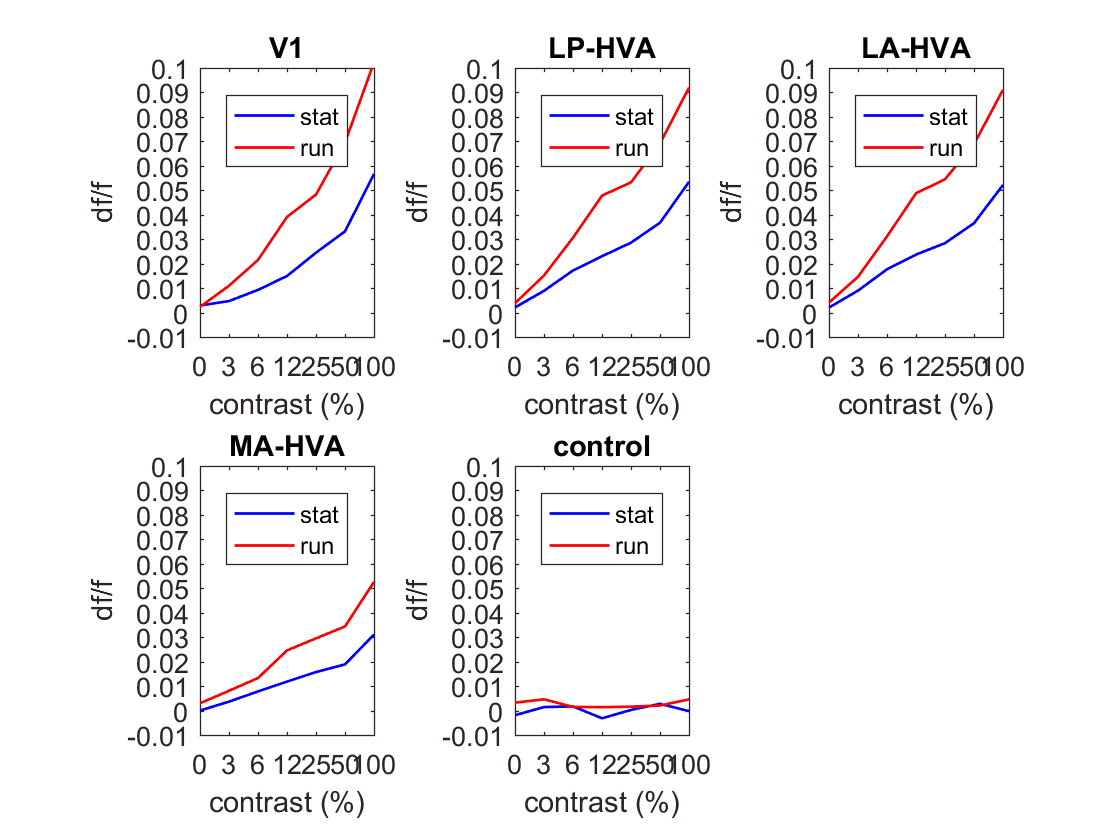

plotCompareBehState_CRF(loRun_allSessAllPtsAllDurs_CRF,hiRun_allSessAllPtsAllDurs_CRF,durat,yMax,yMin,yLimit,x_axis,xMax,xMin,xLimit,stateLegend,uniqueContrasts,reigons,nGroup);


% Lo vs Hi PUPIL

% lo pup group CRF matrix
state = 'loPup'

state = loPup

clear loPup_allSessAllPtsAllDurs_CRF
[loPup_allSessAllPtsAllDurs_CRF] = CRF_byBehState(nGroup,state,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria,groupPTSdfof,groupPeakFrameIdx,groupBaselineIdx,groupIdxStatTrials,groupIdxRunTrials,groupIdxSmallPupilTrials,groupIdxLargePupilTrials,visArea,durat,cont,conAndDurOrderedByTrialMeetCriteria,uniqueContrasts,uniqueDurations);
sizeLoPupAllSessAllPtsAllDurs_CRF = size(loPup_allSessAllPtsAllDurs_CRF)

sizeLoPupAllSessAllPtsAllDurs_CRF =      1     7     5



% hi pup group CRF matrix
state = 'hiPup'

state = hiPup

clear hiPup_allSessAllPtsAllDurs_CRF
[hiPup_allSessAllPtsAllDurs_CRF] = CRF_byBehState(nGroup,state,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria,groupPTSdfof,groupPeakFrameIdx,groupBaselineIdx,groupIdxStatTrials,groupIdxRunTrials,groupIdxSmallPupilTrials,groupIdxLargePupilTrials,visArea,durat,cont,conAndDurOrderedByTrialMeetCriteria,uniqueContrasts,uniqueDurations);
sizeHiPupAllSessAllPtsAllDurs_CRF = size(hiPup_allSessAllPtsAllDurs_CRF)

sizeHiPupAllSessAllPtsAllDurs_CRF =      1     7     5



% crf pup figs 
stateLegend = {'loPup','hiPup'}

stateLegend =     'loPup'    'hiPup'


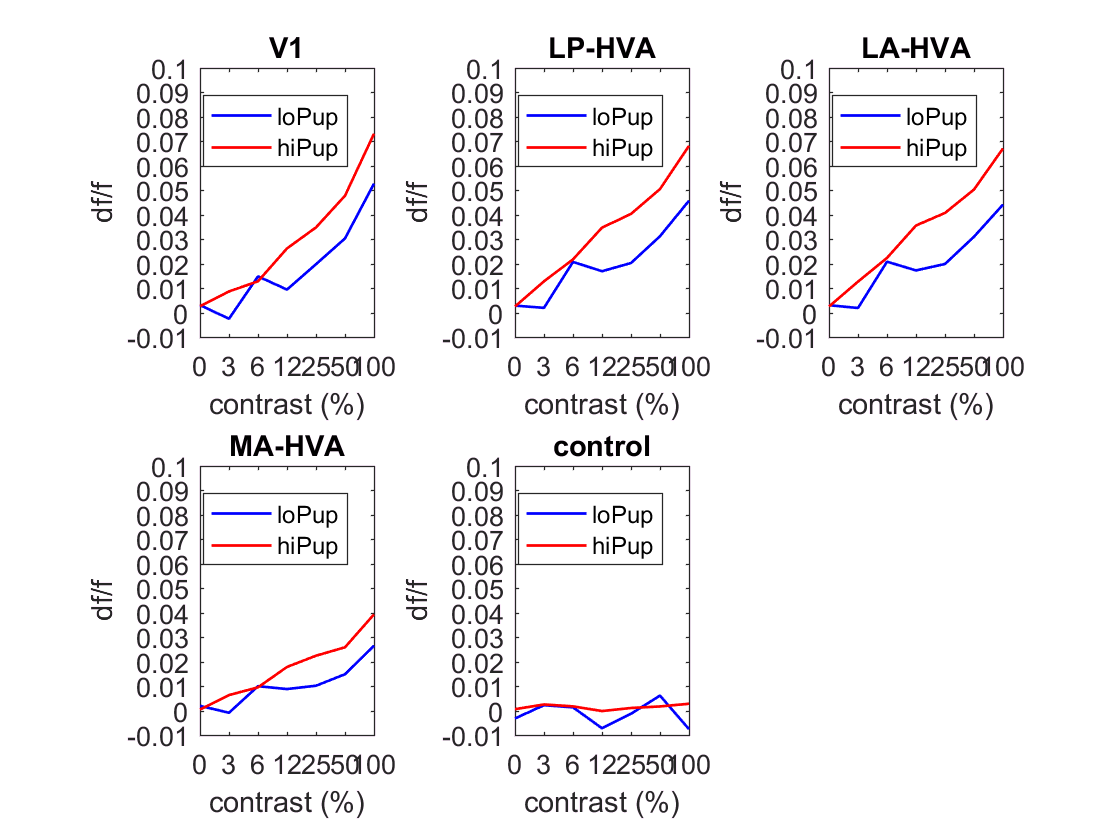

plotCompareBehState_CRF(loPup_allSessAllPtsAllDurs_CRF,hiPup_allSessAllPtsAllDurs_CRF,durat,yMax,yMin,yLimit,x_axis,xMax,xMin,xLimit,stateLegend,uniqueContrasts,reigons,nGroup);

% MEAN DF vs FRAMES (Q: why do both functions take both state inputs at same 
% time when each only outputs one or the other state....? A: b/c the function is for eiather
% beh state and needs both state trial idx inputs. Note: use GLOBAL next time)

visArea = 1; % one area at a time, shows all contrasts (Q: could do this other way around?)
%visArea = 1:length(groupRoundXpts{1,n})
durat = 1:length(uniqueDurations)

durat =      1


cont = 1:length(uniqueContrasts)

cont =      1     2     3     4     5     6     7



% LOCOMOTION

state = 'loRun'

state = loRun

[loRun_mnTraceAllConsDursPts] = MnTrace_byBehState(nGroup,state,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria,groupPTSdfof,groupPeakFrameIdx,groupBaselineIdx,groupIdxStatTrials,groupIdxRunTrials,groupIdxSmallPupilTrials,groupIdxLargePupilTrials,visArea,durat,cont,conAndDurOrderedByTrialMeetCriteria,uniqueContrasts,uniqueDurations);
% con x frames x dur x points x sessions
sizeLoRun_mnTraceAllConsDursPts = size(loRun_mnTraceAllConsDursPts)

sizeLoRun_mnTraceAllConsDursPts =      7    18



state = 'hiRun'

state = hiRun

[hiRun_mnTraceAllConsDursPts] = MnTrace_byBehState(nGroup,state,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria,groupPTSdfof,groupPeakFrameIdx,groupBaselineIdx,groupIdxStatTrials,groupIdxRunTrials,groupIdxSmallPupilTrials,groupIdxLargePupilTrials,visArea,durat,cont,conAndDurOrderedByTrialMeetCriteria,uniqueContrasts,uniqueDurations);
% con x frames x dur x points x sessions
sizeHiRun_mnTraceAllConsDursPts = size(hiRun_mnTraceAllConsDursPts)

sizeHiRun_mnTraceAllConsDursPts =      7    18



% for mean Trace figs
yMax = 0.1;
yMin = -0.01;
yLimit = [yMin yMax];
%x_axis = [1:length(uniqueContrasts)];
%xMax = max(x_axis);
%xMin = min(x_axis);
%xLimit = [xMin xMax];

% locomotion mean trace figs
stateLegend = {'stat','run'}

stateLegend =     'stat'    'run'


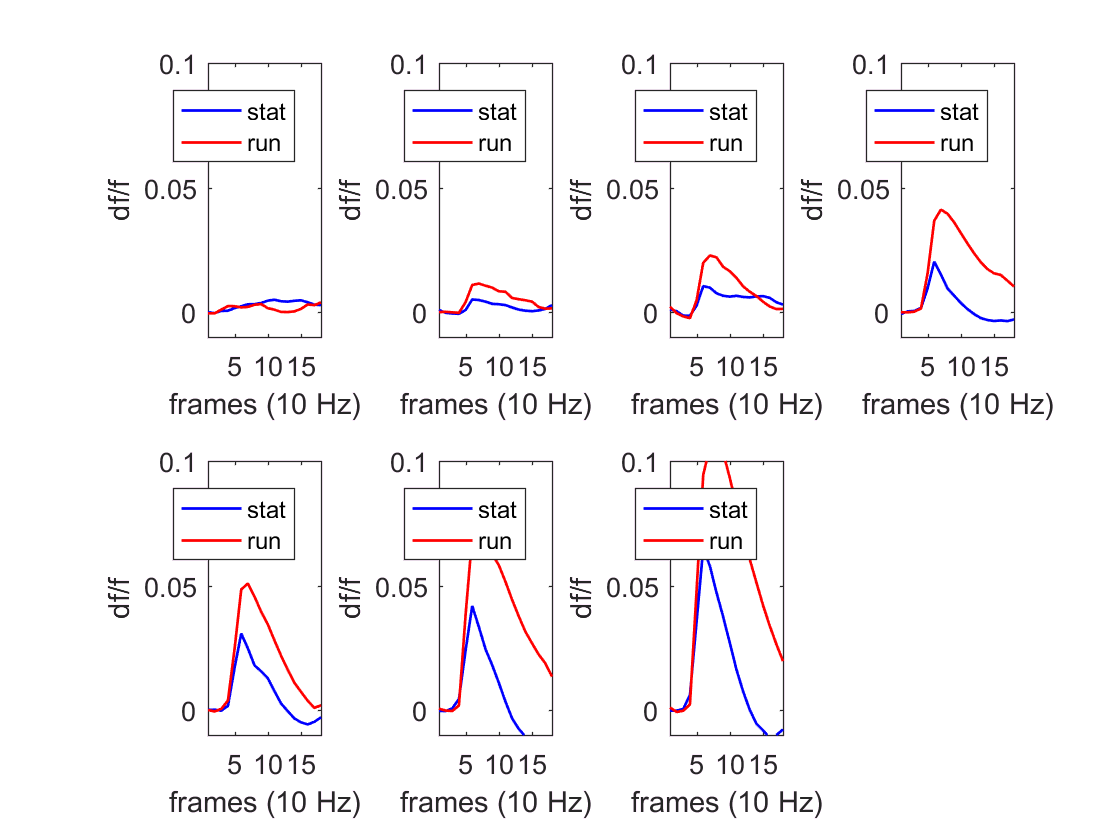

plotCompareBehState_mnTrace(loRun_mnTraceAllConsDursPts,hiRun_mnTraceAllConsDursPts,cons4axes,visArea,durat,cont,yMax,yMin,yLimit,stateLegend,nGroup)


% Mean Trace PUPIL

state = 'loPup'

state = loPup

[loPup_mnTraceAllConsDursPts] = MnTrace_byBehState(nGroup,state,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria,groupPTSdfof,groupPeakFrameIdx,groupBaselineIdx,groupIdxStatTrials,groupIdxRunTrials,groupIdxSmallPupilTrials,groupIdxLargePupilTrials,visArea,durat,cont,conAndDurOrderedByTrialMeetCriteria,uniqueContrasts,uniqueDurations);
% con x frames x dur x points x sessions
sizeLoPup_mnTraceAllConsDursPts = size(loPup_mnTraceAllConsDursPts)

sizeLoPup_mnTraceAllConsDursPts =      7    18



state = 'hiPup'

state = hiPup

[hiPup_mnTraceAllConsDursPts] = MnTrace_byBehState(nGroup,state,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria,groupPTSdfof,groupPeakFrameIdx,groupBaselineIdx,groupIdxStatTrials,groupIdxRunTrials,groupIdxSmallPupilTrials,groupIdxLargePupilTrials,visArea,durat,cont,conAndDurOrderedByTrialMeetCriteria,uniqueContrasts,uniqueDurations);
% con x frames x dur x points x sessions
sizeHiPup_mnTraceAllConsDursPts = size(hiPup_mnTraceAllConsDursPts)

sizeHiPup_mnTraceAllConsDursPts =      7    18



% pupil mean trace figs
stateLegend = {'loPup','hiPup'}

stateLegend =     'loPup'    'hiPup'


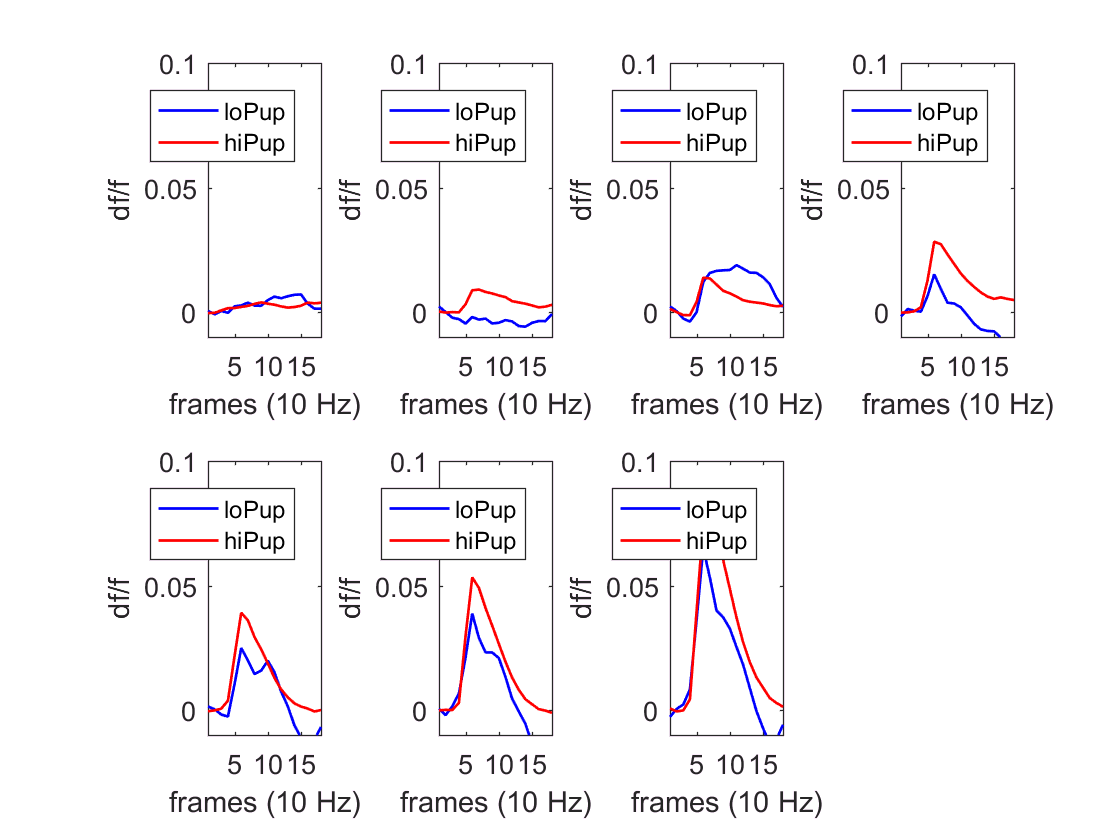

plotCompareBehState_mnTrace(loPup_mnTraceAllConsDursPts,hiPup_mnTraceAllConsDursPts,cons4axes,visArea,durat,cont,yMax,yMin,yLimit,stateLegend,nGroup)

% Mean CRF Per POINT 

% This requires group matrix first...
% making mean CRF, which is needed for interp function 
% and for plotting with the interped trace

% which areas/stimulus parameters to loop over:
n = 1; % this is just to get the number of points
visArea = 1:length(groupRoundXpts{1,n});
%durat = 1:length(uniqueDurations)
durat = 1 % (durat = 1 means 100 ms in final set of expts)

durat =      1


cont = 1:length(uniqueContrasts)

cont =      1     2     3     4     5     6     7



% LOCO

% getting mean CRF ACROSS SESSIONS & STD ERR ACROSS SESSIONS 
% note: this code is roughtly the same as that w/in code from groupMeta.mlx wehere CRFs are calculated 
% and plotted from the data in, 
% except this code doesn't make fig w/in same function, and outputs the matrix to be plotted:
% LO BEH STATE
[loRun_mnCRF_acrossSess_AllDurAllPts,loRun_stdErrCRF_acrossSess_allPts] = mean_CRF_AcrossSessions(loPup_allSessAllPtsAllDurs_CRF,visArea,durat,cont);
size_loRun_mnCRF_acrossSess_AllDurAllPts = size(loRun_mnCRF_acrossSess_AllDurAllPts);
size_loRun_stdErrCRF_acrossSess_allPts = size(loRun_stdErrCRF_acrossSess_allPts);
% HI BEH STATE                                                                                                            
[hiRun_mnCRF_acrossSess_AllDurAllPts,hiRun_stdErrCRF_acrossSess_allPts] = mean_CRF_AcrossSessions(hiPup_allSessAllPtsAllDurs_CRF,visArea,durat,cont);
size_hiRun_mnCRF_acrossSess_AllDurAllPts = size(hiRun_mnCRF_acrossSess_AllDurAllPts);
size_hiRun_stdErrCRF_acrossSess_allPts = size(hiRun_stdErrCRF_acrossSess_allPts);

% PUPIL

% LO BEH STATE
[loPup_mnCRF_acrossSess_AllDurAllPts,loPup_stdErrCRF_acrossSess_allPts] = mean_CRF_AcrossSessions(loPup_allSessAllPtsAllDurs_CRF,visArea,durat,cont);
size_loPup_mnCRF_acrossSess_AllDurAllPts = size(loPup_mnCRF_acrossSess_AllDurAllPts);
size_loPup_stdErrCRF_acrossSess_allPts = size(loPup_stdErrCRF_acrossSess_allPts);
% HI BEH STATE                                                                                                            
[hiPup_mnCRF_acrossSess_AllDurAllPts,hiPup_stdErrCRF_acrossSess_allPts] = mean_CRF_AcrossSessions(hiPup_allSessAllPtsAllDurs_CRF,visArea,durat,cont);
size_hiPup_mnCRF_acrossSess_AllDurAllPts = size(hiPup_mnCRF_acrossSess_AllDurAllPts);
size_hiPup_stdErrCRF_acrossSess_allPts = size(hiPup_stdErrCRF_acrossSess_allPts);

% INTERP - LOCO

% loop vars for interp, calc C50, & plot
% which areas/stimulus parameters to loop over:
n = 1; % this is just to get the number of points
%durat = 1:length(uniqueDurations)
durat = 1 % (durat = 1 means 100 ms in final set of expts)

durat =      1


visArea = 1:length(groupRoundXpts{1,n})

visArea =      1     2     3     4     5


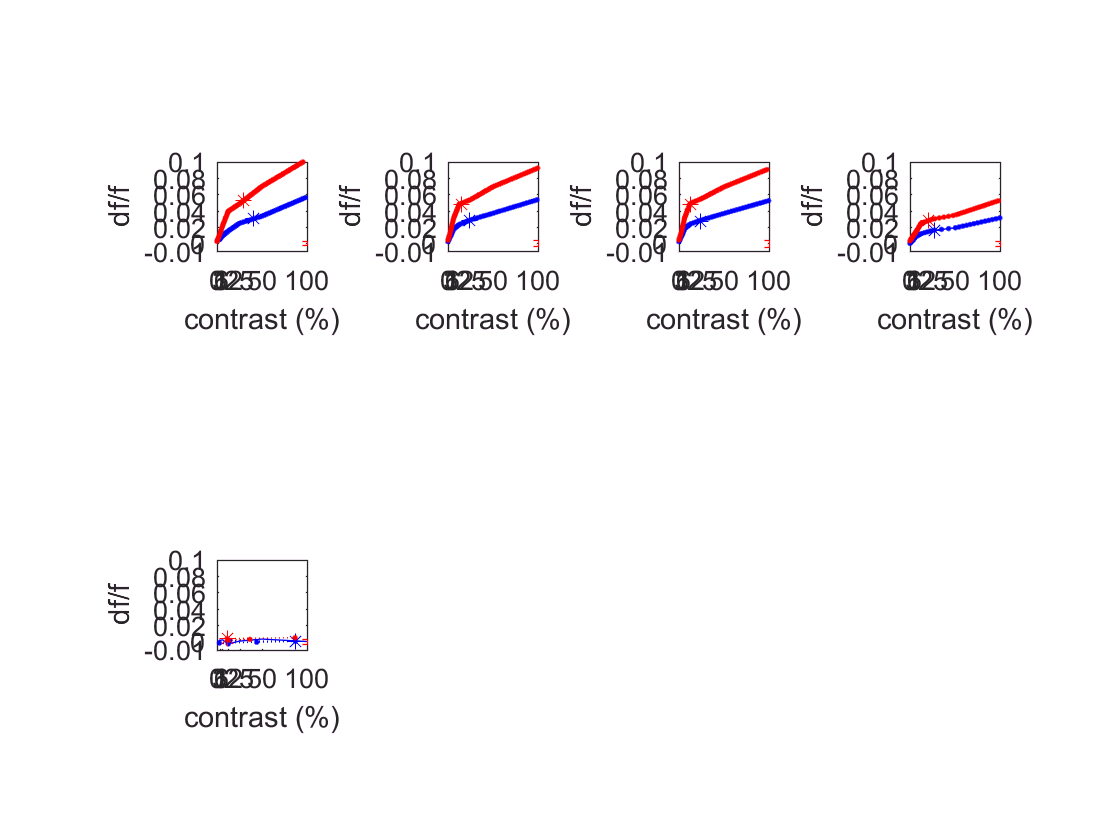


for d = durat
    
    clear lo_yi_interpedConsCurve_allPts{}
    clear lo_xi_isDf_higherRes_allPts{} 
    clear lo_C50_allPts
    clear lo_df_at_C50_allPts
    
    clear hi_yi_interpedConsCurve_allPts{}
    clear hi_xi_isDf_higherRes_allPts{} 
    clear hi_C50_allPts
    clear hi_df_at_C50_allPts
    
    for i = visArea

        % INTERP - LO beh state
        % take the ith CRF
        ith_mnCRF_acrossSess_AllDurAllPts_lo = loRun_mnCRF_acrossSess_AllDurAllPts(i,:);
        % x is df vector
        x_is_df = ith_mnCRF_acrossSess_AllDurAllPts_lo;
        % resolution of interpolation 
        higherRes = 1/1000; 
        lo_xi_isDf_higherRes = min(x_is_df):higherRes:max(x_is_df);
        % the y input to inpterp() is the thing you want interpolated according to the resolution set above
        y_is_cons = uniqueContrasts;
        % interpolate contrast
        lo_yi_interpedConsCurve = interp1(x_is_df,y_is_cons,lo_xi_isDf_higherRes);
        
        % find con associated 1/2 max df/range value
        % find 1/2 max df
        % take the range of df (max df - min df)
        range = max(ith_mnCRF_acrossSess_AllDurAllPts_lo)-min(ith_mnCRF_acrossSess_AllDurAllPts_lo);
        % divide range by 2
        halfOf_range = range/2;
        % subtract 1/2 of range from max df to get the yvalue we want to query the interpolated contrast for
        lo_df_at_C50 = max(ith_mnCRF_acrossSess_AllDurAllPts_lo)-halfOf_range;
        
        % find C50 on interpolated curve
        % find first higher res df value greater than df_at_C50
        idx_df_lo_Res_aboveC50 = min(find(lo_xi_isDf_higherRes>lo_df_at_C50));
        % use index to find associated interped CON value
        lo_C50 = lo_yi_interpedConsCurve(1,idx_df_lo_Res_aboveC50);
        
        % COLLECT LO VARS to plot
        lo_yi_interpedConsCurve_allPts{i,:} = lo_yi_interpedConsCurve;
        lo_xi_isDf_higherRes_allPts{i,:} = lo_xi_isDf_higherRes;
        lo_C50_allPts(i,:) = lo_C50;
        lo_df_at_C50_allPts(i,:) = lo_df_at_C50;
        
        % INTERP - HI beh state
        % take the ith CRF
        ith_mnCRF_acrossSess_AllDurAllPts_hi = hiRun_mnCRF_acrossSess_AllDurAllPts(i,:);
        % x is df vector
        x_is_df = ith_mnCRF_acrossSess_AllDurAllPts_hi;
        % resolution of interpolation 
        higherRes = 1/1000; 
        hi_xi_isDf_higherRes = min(x_is_df):higherRes:max(x_is_df);
        % the y input to inpterp() is the thing you want interpolated according to the resolution set above
        y_is_cons = uniqueContrasts;
        % interpolate contrast
        hi_yi_interpedConsCurve = interp1(x_is_df,y_is_cons,hi_xi_isDf_higherRes);
        % find con associated 1/2 max df/range value
        % find 1/2 max df
        % take the range of df (max df - min df)
        
        range = max(ith_mnCRF_acrossSess_AllDurAllPts_hi)-min(ith_mnCRF_acrossSess_AllDurAllPts_hi);
        % divide range by 2
        halfOf_range = range/2;
        % subtract 1/2 of range from max df to get the yvalue we want to query the interpolated contrast for
        hi_df_at_C50 = max(ith_mnCRF_acrossSess_AllDurAllPts_hi)-halfOf_range;
        
        % find C50 on interpolated curve
        % find first higher res df value greater than df_at_C50
        idx_df_hiRes_aboveC50 = min(find(hi_xi_isDf_higherRes>hi_df_at_C50));
        % use index to find associated interped cCON value
        hi_C50 = hi_yi_interpedConsCurve(1,idx_df_hiRes_aboveC50);
        
        % COLLECT VARS to plot
        hi_yi_interpedConsCurve_allPts{i,:} = hi_yi_interpedConsCurve;
        hi_xi_isDf_higherRes_allPts{i,:} = hi_xi_isDf_higherRes;
        hi_C50_allPts(i,:) = hi_C50;
        hi_df_at_C50_allPts(i,:) = hi_df_at_C50;

    end % end i loop
    
end % end d loop

    % PLOT INTERP + CRF, LOCO, BOTH beh STATES one FIG

% for FIGURE/Axes
yMax = 0.1;
yMin = -0.01;
yLimit = [yMin yMax];
yt = [-0.01 0 0.02 0.04 0.06 0.08 0.1];

%x_axis = [1:length(uniqueContrasts)];
xMax = max(uniqueContrasts);
xMin = min(uniqueContrasts);
xLimit = [xMin xMax];
xt=[0 0.03 0.06 0.12 0.25 0.5 1];
xtl = {'0'; '3' ; '6' ; '12' ; '25' ; '50'; '100'}; 
%xtl={'0'; '0.03' ; '0.06' ; '0.12' ; '0.25' ; '0.5'; '1'};

stateLegend = {'stat','run'};

figure

for i = visArea % leave out control area
    
    subplot(2,4,i)
    
    if nGroup == 1
            
        plot(uniqueContrasts,loRun_mnCRF_acrossSess_AllDurAllPts(i,:),'b')
        hold on 
        plot(lo_yi_interpedConsCurve_allPts{i},lo_xi_isDf_higherRes_allPts{i},'b:.')
        hold on 
        plot(lo_C50_allPts(i,:),lo_df_at_C50_allPts(i,:),'b*')
        
        hold on
       
        errorbar(uniqueContrasts,hiRun_mnCRF_acrossSess_AllDurAllPts(i,:),'r')
        hold on 
        plot(hi_yi_interpedConsCurve_allPts{i},hi_xi_isDf_higherRes_allPts{i},'r:.')
        hold on 
        plot(hi_C50_allPts(i,:),hi_df_at_C50_allPts(i,:),'r*')
    
    else
        
        errorbar(uniqueContrasts,loRun_mnCRF_acrossSess_AllDurAllPts(i,:),loRun_stdErrCRF_acrossSess_allPts(i,:),'b')
        hold on 
        plot(lo_yi_interpedConsCurve_allPts{i},lo_xi_isDf_higherRes_allPts{i},'b:.')
        hold on 
        plot(lo_C50_allPts(i,:),lo_df_at_C50_allPts(i,:),'b*')
        
        hold on
       
        errorbar(uniqueContrasts,hiRun_mnCRF_acrossSess_AllDurAllPts(i,:),hiRun_stdErrCRF_acrossSess_allPts(i,:),'r')
        hold on 
        plot(hi_yi_interpedConsCurve_allPts{i},hi_xi_isDf_higherRes_allPts{i},'r:.')
        hold on 
        plot(hi_C50_allPts(i,:),hi_df_at_C50_allPts(i,:),'r*')
    
    end
    
    ylim(yLimit) 
    xlim(xLimit)
    ylabel('df/f')
    xlabel('contrast (%)')                
    set(gca,'xtick',xt); 
    set(gca,'xticklabel',xtl);
    set(gca,'YTick',yt)
    
    axis square

end 

% INTERP - PUPIL

% loop vars for interp, calc C50, & plot
% which areas/stimulus parameters to loop over:
n = 1; % this is just to get the number of points
%durat = 1:length(uniqueDurations)
durat = 1 % (durat = 1 means 100 ms in final set of expts)

durat =      1


visArea = 1:length(groupRoundXpts{1,n})

visArea =      1     2     3     4     5


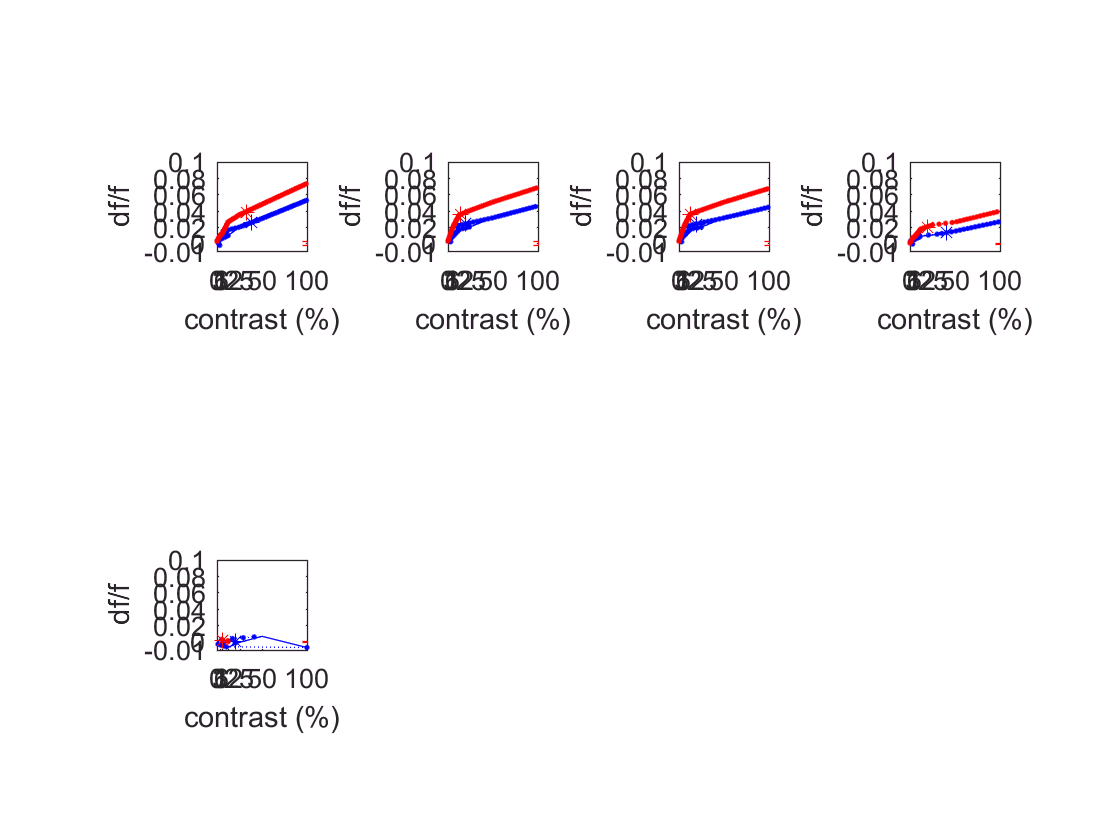


for d = durat
    
    clear lo_yi_interpedConsCurve_allPts{}
    clear lo_xi_isDf_higherRes_allPts{} 
    clear lo_C50_allPts
    clear lo_df_at_C50_allPts
    
    clear hi_yi_interpedConsCurve_allPts{}
    clear hi_xi_isDf_higherRes_allPts{} 
    clear hi_C50_allPts
    clear hi_df_at_C50_allPts
    
    for i = visArea

        % INTERP - LO beh state
        % take the ith CRF
        ith_mnCRF_acrossSess_AllDurAllPts_lo = loPup_mnCRF_acrossSess_AllDurAllPts(i,:);
        % x is df vector
        x_is_df = ith_mnCRF_acrossSess_AllDurAllPts_lo;
        % resolution of interpolation 
        higherRes = 1/1000; 
        lo_xi_isDf_higherRes = min(x_is_df):higherRes:max(x_is_df);
        % the y input to inpterp() is the thing you want interpolated according to the resolution set above
        y_is_cons = uniqueContrasts;
        % interpolate contrast
        lo_yi_interpedConsCurve = interp1(x_is_df,y_is_cons,lo_xi_isDf_higherRes);
        
        % find con associated 1/2 max df/range value
        % find 1/2 max df
        % take the range of df (max df - min df)
        range = max(ith_mnCRF_acrossSess_AllDurAllPts_lo)-min(ith_mnCRF_acrossSess_AllDurAllPts_lo);
        % divide range by 2
        halfOf_range = range/2;
        % subtract 1/2 of range from max df to get the yvalue we want to query the interpolated contrast for
        lo_df_at_C50 = max(ith_mnCRF_acrossSess_AllDurAllPts_lo)-halfOf_range;
        
        % find C50 on interpolated curve
        % find first higher res df value greater than df_at_C50
        idx_df_lo_Res_aboveC50 = min(find(lo_xi_isDf_higherRes>lo_df_at_C50));
        % use index to find associated interped CON value
        lo_C50 = lo_yi_interpedConsCurve(1,idx_df_lo_Res_aboveC50);
        
        % COLLECT LO VARS to plot
        lo_yi_interpedConsCurve_allPts{i,:} = lo_yi_interpedConsCurve;
        lo_xi_isDf_higherRes_allPts{i,:} = lo_xi_isDf_higherRes;
        lo_C50_allPts(i,:) = lo_C50;
        lo_df_at_C50_allPts(i,:) = lo_df_at_C50;
        
        % INTERP - HI beh state
        % take the ith CRF
        ith_mnCRF_acrossSess_AllDurAllPts_hi = hiPup_mnCRF_acrossSess_AllDurAllPts(i,:);
        % x is df vector
        x_is_df = ith_mnCRF_acrossSess_AllDurAllPts_hi;
        % resolution of interpolation 
        higherRes = 1/1000; 
        hi_xi_isDf_higherRes = min(x_is_df):higherRes:max(x_is_df);
        % the y input to inpterp() is the thing you want interpolated according to the resolution set above
        y_is_cons = uniqueContrasts;
        % interpolate contrast
        hi_yi_interpedConsCurve = interp1(x_is_df,y_is_cons,hi_xi_isDf_higherRes);
        % find con associated 1/2 max df/range value
        % find 1/2 max df
        % take the range of df (max df - min df)
        
        range = max(ith_mnCRF_acrossSess_AllDurAllPts_hi)-min(ith_mnCRF_acrossSess_AllDurAllPts_hi);
        % divide range by 2
        halfOf_range = range/2;
        % subtract 1/2 of range from max df to get the yvalue we want to query the interpolated contrast for
        hi_df_at_C50 = max(ith_mnCRF_acrossSess_AllDurAllPts_hi)-halfOf_range;
        
        % find C50 on interpolated curve
        % find first higher res df value greater than df_at_C50
        idx_df_hiRes_aboveC50 = min(find(hi_xi_isDf_higherRes>hi_df_at_C50));
        % use index to find associated interped cCON value
        hi_C50 = hi_yi_interpedConsCurve(1,idx_df_hiRes_aboveC50);
        
        % COLLECT VARS to plot
        hi_yi_interpedConsCurve_allPts{i,:} = hi_yi_interpedConsCurve;
        hi_xi_isDf_higherRes_allPts{i,:} = hi_xi_isDf_higherRes;
        hi_C50_allPts(i,:) = hi_C50;
        hi_df_at_C50_allPts(i,:) = hi_df_at_C50;

    end % end i loop
    
end % end d loop

% PLOT INTERP + CRF, PUPIL, BOTH beh STATES one FIG

% for FIGURE/Axes
yMax = 0.1;
yMin = -0.01;
yLimit = [yMin yMax];
yt = [-0.01 0 0.02 0.04 0.06 0.08 0.1];

%x_axis = [1:length(uniqueContrasts)];
xMax = max(uniqueContrasts);
xMin = min(uniqueContrasts);
xLimit = [xMin xMax];
xt=[0 0.03 0.06 0.12 0.25 0.5 1];
xtl = {'0'; '3' ; '6' ; '12' ; '25' ; '50'; '100'}; 
%xtl={'0'; '0.03' ; '0.06' ; '0.12' ; '0.25' ; '0.5'; '1'};

stateLegend = {'stat','run'};

figure

for i = visArea % leave out control area
    
    subplot(2,4,i)
    
    if nGroup == 1
            
        plot(uniqueContrasts,loRun_mnCRF_acrossSess_AllDurAllPts(i,:),'b')
        hold on 
        plot(lo_yi_interpedConsCurve_allPts{i},lo_xi_isDf_higherRes_allPts{i},'b:.')
        hold on 
        plot(lo_C50_allPts(i,:),lo_df_at_C50_allPts(i,:),'b*')
        
        hold on
       
        errorbar(uniqueContrasts,hiRun_mnCRF_acrossSess_AllDurAllPts(i,:),'r')
        hold on 
        plot(hi_yi_interpedConsCurve_allPts{i},hi_xi_isDf_higherRes_allPts{i},'r:.')
        hold on 
        plot(hi_C50_allPts(i,:),hi_df_at_C50_allPts(i,:),'r*')
    
    else
        
        errorbar(uniqueContrasts,loRun_mnCRF_acrossSess_AllDurAllPts(i,:),loRun_stdErrCRF_acrossSess_allPts(i,:),'b')
        hold on 
        plot(lo_yi_interpedConsCurve_allPts{i},lo_xi_isDf_higherRes_allPts{i},'b:.')
        hold on 
        plot(lo_C50_allPts(i,:),lo_df_at_C50_allPts(i,:),'b*')
        
        hold on
       
        errorbar(uniqueContrasts,hiRun_mnCRF_acrossSess_AllDurAllPts(i,:),hiRun_stdErrCRF_acrossSess_allPts(i,:),'r')
        hold on 
        plot(hi_yi_interpedConsCurve_allPts{i},hi_xi_isDf_higherRes_allPts{i},'r:.')
        hold on 
        plot(hi_C50_allPts(i,:),hi_df_at_C50_allPts(i,:),'r*')
    
    end
    
    ylim(yLimit) 
    xlim(xLimit)
    ylabel('df/f')
    xlabel('contrast (%)')                
    set(gca,'xtick',xt); 
    set(gca,'xticklabel',xtl);
    set(gca,'YTick',yt)
    
    axis square

end 

durat = 1
%visArea = 1
visArea = 1:length(groupRoundXpts{1,n})
%sess = 1
sess = 1:nGroup

global durat 
global visArea 
global sess 

global uniqueContrasts

[lo_yi_interpedConsCurve_allPtsAllSess,lo_xi_isDf_higherRes_allPtsAllSess,lo_C50_allPtsAllSess,lo_df_at_C50_allPtsAllSess,hi_yi_interpedConsCurve_allPtsAllSess,hi_xi_isDf_higherRes_allPtsAllSess,hi_C50_allPtsAllSess,hi_df_at_C50_allPtsAllSess] = makeC50_test(loRun_allSessAllPtsAllDurs_CRF,hiRun_allSessAllPtsAllDurs_CRF);
% the c50 output vars are pts x column w/df values at c50 x sess (probs better dimsional arrangement for this...)
lo_C50_allPtsAllSess = squeeze(lo_C50_allPtsAllSess);
hi_C50_allPtsAllSess = squeeze(hi_C50_allPtsAllSess);
% w/squeeze they are points x sess
size(lo_C50_allPtsAllSess)
size(hi_C50_allPtsAllSess)